# **電力ネットワークの利用・定義**

**本ファイルでは電力システムにコントローラをつけてシミュレーションを行う方法を説明します。**

**GUILDA上で、電力系統モデルを作成するには２通りの方法があります。**

**GUILDAに既に実装されているベンチマークモデルの電力モデルを用いる、もしくは自分で電力ネットワークを定義する方法です。**

**それぞれに対応するよう、「1.ベンチマークモデルの使用」「2.新しいモデルの定義」の２章立てで紹介します。**

**作業行程としては、以下の赤枠で囲った部分の作業に対応します。**

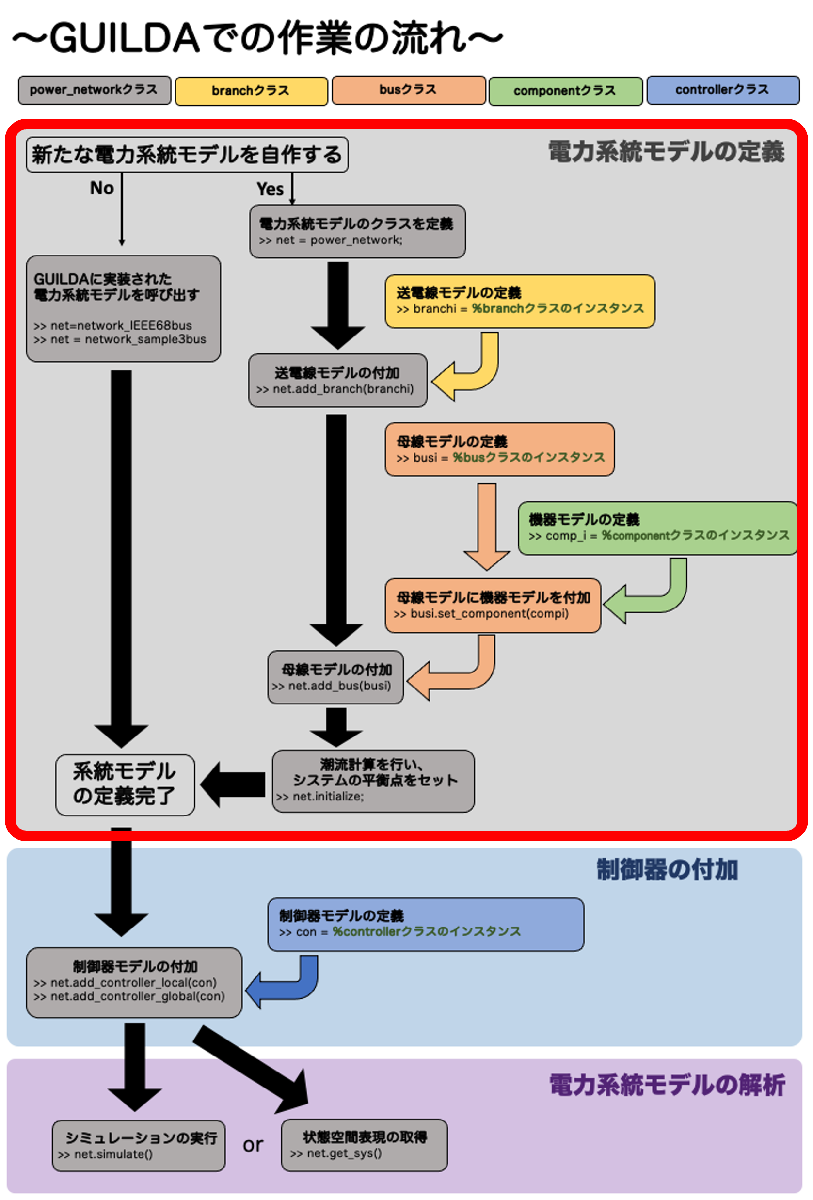

# **1.ベンチマークモデルの使用**

**GUILDAにはベンチマークモデルとして**`IEEE68bus`**モデルと**`IEEE9bus`**モデルの２つが実装されています。**

**手始めにシミュレーションを行ってみたい、制御器の性能評価のため適当なネットワークモデルが欲しい、といった場合はこちらを利用するのが良いでしょう。**

## `・IEEE68busモデル`

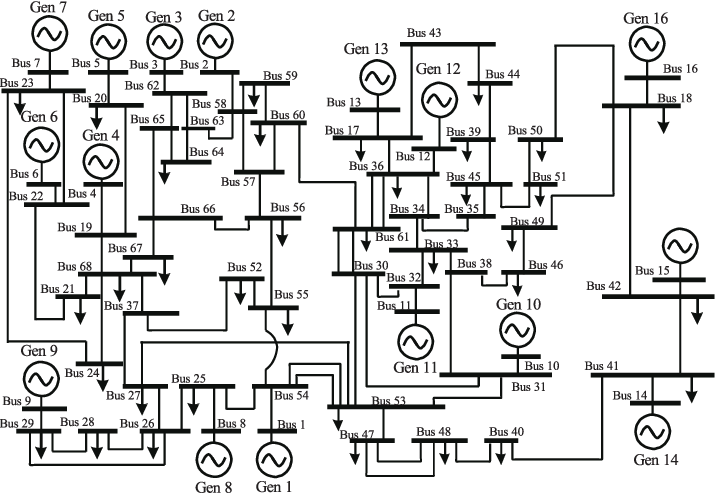

以下のように関数を呼び出すことで、`IEEE68bus`モデルを生成できます。

 
net = network.IEEE68bus();

## `・IEEE9busモデル`

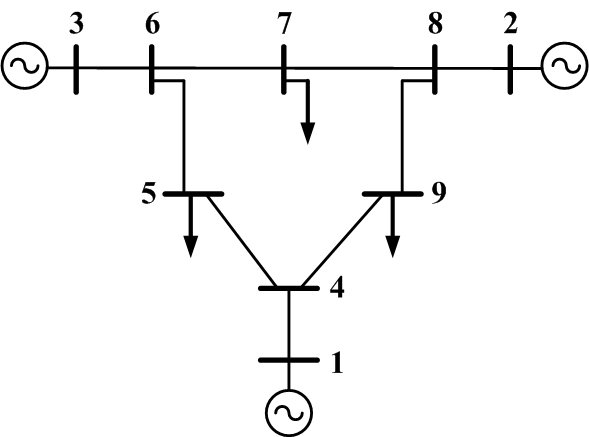

以下のように関数を呼び出すことで、`IEEE9bus`モデルを生成できます。

 
net = network.IEEE9bus_past();

# **2.新しいモデルの定義**

上の節までは、パラメータや機器の種類まで全て定められているベンチマークモデルを呼び出す方法を示しました。

本節では、１から自由に電力系統モデルを作成する方法を紹介します。ここでは、試しに以下の電力系統モデルを作成したいと思います。

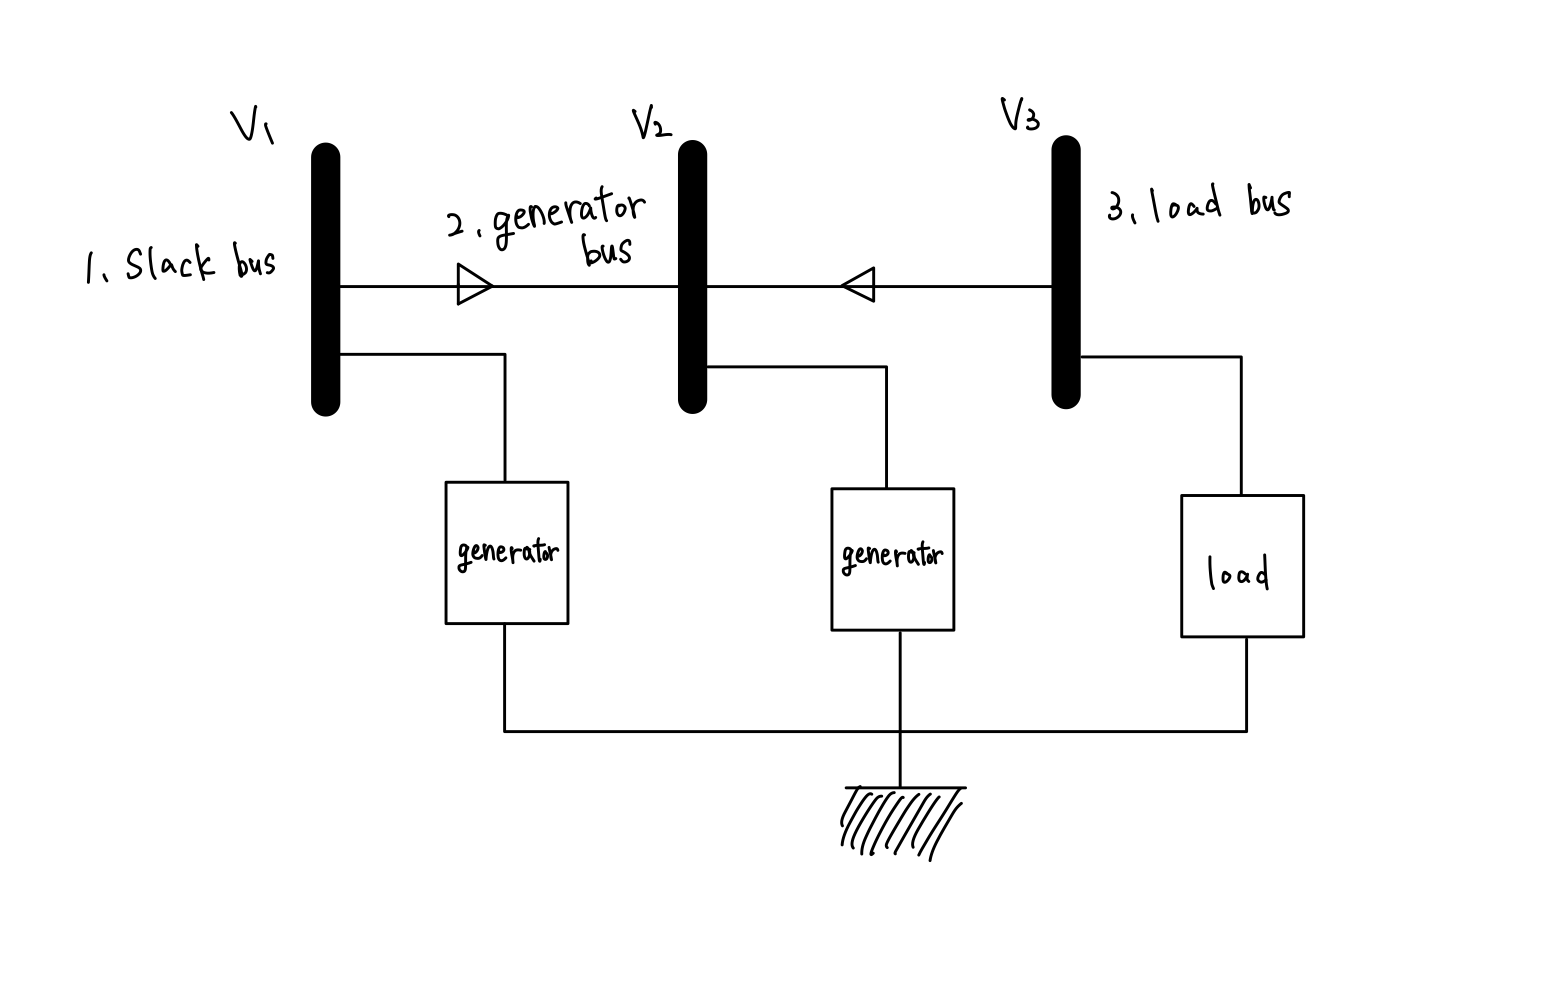

## **1. power_networkクラスの定義**

では、まず電力系統モデルの大枠となる`power_network`クラスを定義します。このクラスには、各母線やブランチ、機器などの情報を整理して格納しておく`properties`と、それらのデータを用いてシミュレーション等の解析を行う`method`が定義されています。この大枠に以下ではデータを代入します。

`power_network`クラスの定義は簡単で以下のように実行するだけです。

 
net = power_network();

## **2. busクラスの定義 >> power_networkクラスへの付加**

次に、母線の種類（PV,PQ,slack）と各母線の潮流設定の値を決定します。

今回は以下のように設定してみます。

表中のP、Q、|V|、∠V はそれぞれ「有効電力」「無効電力」「母線電圧の大きさ」「電圧の偏角」を指しています。母線の種類や潮流設定の各パラメータの意味に関しては「[Model_Bus.mlx](matlab:open('./Model_Bus.mlx'))」を参考にして下さい。

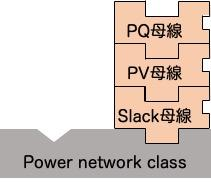

**GUILDA上での実装方法**

母線の定義についても、送電線の定義と同様にbusクラスの変数を定義し、power_networkクラスのadd_busというmethodを用いて代入します。また、busクラスにはbus_PV、bus_PQ、bus_slackという子クラスが定義されており各母線の種類ごとにこれらを使い分けて定義します。

- slack母線の場合:

- PV母線の場合:

- PQ母線の場合:

各関数の引数については「[`ClassManual/Bus_variety.mlx`](matlab:open('./ClassManual/Bus_variety.mlx'))」を参照してください。それでは、実際に各母線の情報を定義していきます。

 
shunt = [0,0];
%母線1の定義
bus_1 = bus.slack(2,0,shunt);
net.add_bus(bus_1);
%母線2の定義
bus_2 = bus.PV(0.5,2,shunt);
net.add_bus(bus_2);
%母線3の定義
bus_3 = bus.PQ(-3,0,shunt);
net.add_bus(bus_3);

## **3. componentクラスの定義 >> busクラスへの付加**

次に今回実装する3busモデルの各母線に付加する機器を決めます。今回のモデルでは母線1と母線2が発電機バス(slack母線とPV母線)、母線3が負荷母線(PQ母線)となっています。また、**今回の実行例では**、発電機母線に接続するのは同期発電機の1軸モデル、負荷母線に接続するのは定インピーダンスモデルの負荷とします。同期発電機の1軸モデルは下式のようになっています。

同期発電機モデルを適応する場合は、上式の各パラメータを決定する必要があります。以上の情報をまとめると下の表のようになります。

なお、同期発電機のパラメータの内、MATLABに実装できる変数名の制約により、そのまま書けない変数名は以下のように書き換えて表現しています。

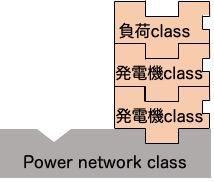

**GUILDA上への実装方法**

機器の定義についても、母線の定義と同様にcomponentクラスの変数を定義し、それを系統に代入します。ただ、機器の定義は、送電網や母線のようにpower_networkクラスに代入するのではなく、power_networkクラスに代入されている、busクラスに代入します。機器は各母線ごとに接続されているためです。

また、同期発電機の1軸モデルはgenerator_1axisというクラスで定義されています。また定インピーダンスモデルはload_impedanceというクラスで定義しています。それでは実際に系統に機器モデルを代入していきます。

 
%系統周波数の定義
omega0 = 60*2*pi;

%母線1に同期発電機の1軸モデルを付加
Xd = 1.569; Xd_p = 0.963; Xq = 0.963; Td_p = 5.14; M = 100; D = 10;
mac_data = table(Xd,Xd_p,Xq,Td_p,M,D);
component1 = component.generator.one_axis(mac_data);

%母線2にも同期発電機の1軸モデルを付加
Xd = 1.220; Xd_p = 0.667; Xq = 0.667; Td_p = 8.97; M = 12; D = 10;
mac_data = table(Xd,Xd_p,Xq,Td_p,M,D);
component2 = component.generator.one_axis(mac_data);

%母線3には定インピーダンスモデルを付加
component3 = component.load.impedance();

% busクラスに各機器クラスを付加する
net.a_bus{1}.set_component(component1);
net.a_bus{2}.set_component(component2);
net.a_bus{3}.set_component(component3);

ここでの注意点は、generator.one_axisの引数のtable型変数の定義についてです。generator_1axisは引数で与えられたテーブル型の変数から、対応する列名の値を抽出していいるため、各パラメータの変数名はコード例と同じになるようにしてください。

## **4. branchクラスの定義 >> power_networkクラスへの付加**

次に送電線(ブランチ)の情報を整理します。GUILDAでは送電線の種類として、π型回路モデルの送電線(branch.piクラス)と、さらに位相調整変圧器も含む送電線(branch.pi_transferクラス)の2種類を実装しています。今回は送電線上に位相調整変圧器は含まれないと仮定します。

実装するモデルには「母線1-母線2」と「母線2-母線3」の２本の送電線が存在します。それぞれの送電線上のインピーダンスと対地静電容量の値は以下とします。

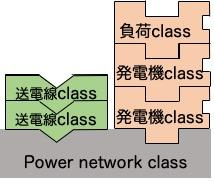

**GUILDA上への実装方法**

送電網の定義手順は、以下のようになります。

- 送電網の情報を代入したbranchクラスの変数を各送電網ごとに定義する。定義方法：branch.pi(from,to,[xreal,ximag],b);

- from , to : 送電線が繋ぐ母線番号

- xreal, x_imag : インピーダンスの実部、虚部

- b : 対地静電容量

- 生成したbranchクラスの変数をpower_networkクラスのadd_branchというmethodを用いて代入する。

では実際に代入しましょう。

 
%母線1と母線2を繋ぐ送電線の定義
branch12 = branch.pi(1,2,[0.010,0.085],0);
net.add_branch(branch12);
%母線2と母線3を繋ぐ送電線の定義
branch23 = branch.pi(2,3,[0.017,0.092],0);
net.add_branch(branch23);

## **5. 初期化処理（潮流計算の実行・平衡点の計算）**

 
net.initialize;

最後に以下のように実行します。これは`power_network`クラス内に定義された`initialize`というmethodを実行しており、プロパティに代入されたパラメータから潮流計算を行い、系統全体のシステムの平衡点を計算し、各値を新たなプロパティとして保存する関数です。

これらの値はワークスペースから閲覧することができます。各パラメータの見方は、「[`Step3_NetProperties.mlx`](matlab:open('./Step3_NetProperties.mlx'))」で紹介します。

`以上で電力系統モデルを定義することができました！`

`次のステップでは、この電力システムに制御器を付加していきます。`

[](matlab:open('./Main.mlx'))　　[](matlab:open('./Step2_AddController.mlx'))